# ELEN 133L Lab 9 -- Ayden Dauenhauer and Aris Ozark

## Part 1

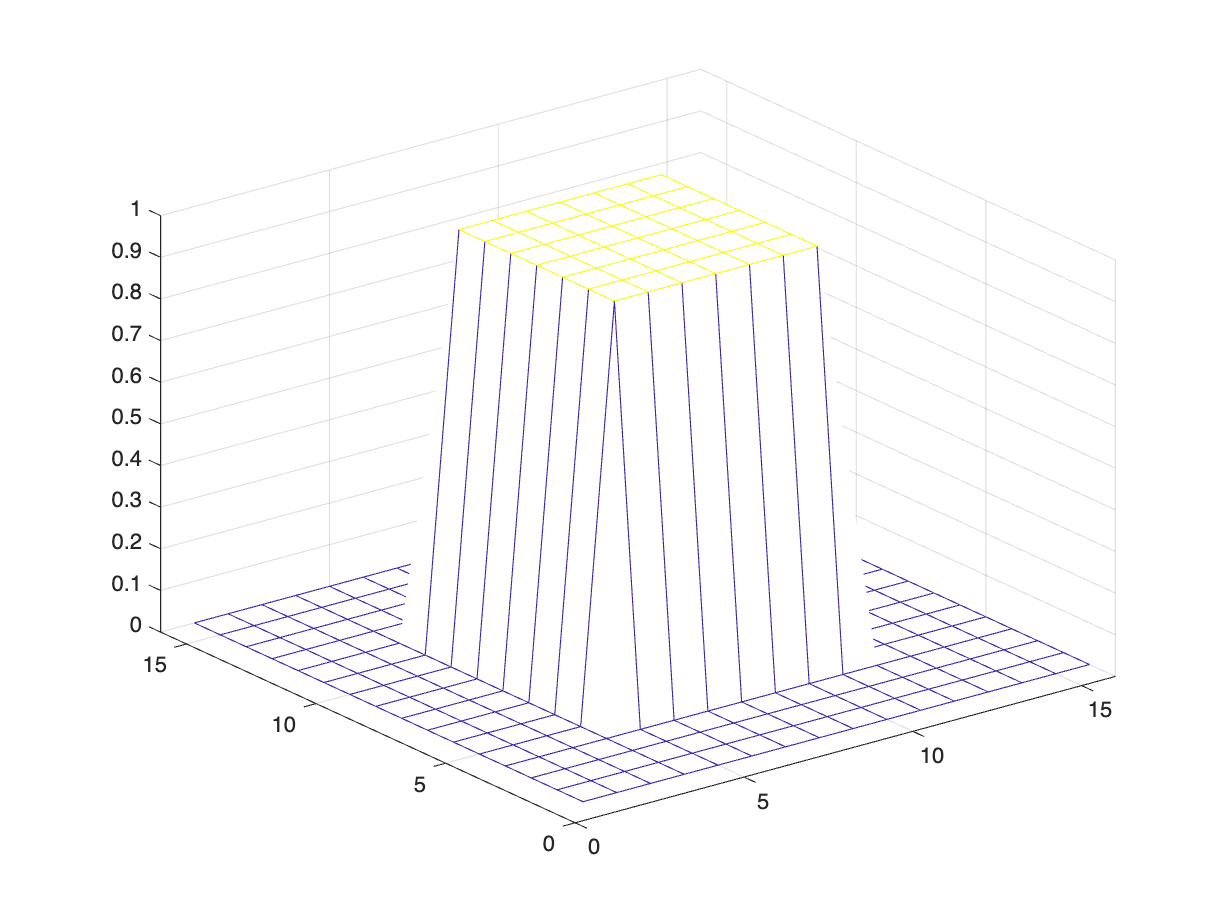

clear all
close all
clc

h1 = [1 2 1];
h2 = [1 0 -1];
h3 = conv(h1, h1);

hA = transpose(h1)*h1;
hB = transpose(h2)*h1;
hC = transpose(h3)*h3;

A1 = zeros(16);
A1(5:11,5:11) = ones(7);
mesh(A1)

size(A1)

ans =     16    16


Aout = conv2(hA,A1);
Aout_sep = conv2(transpose(h1),h1,A1);
size(Aout)

ans =     18    18


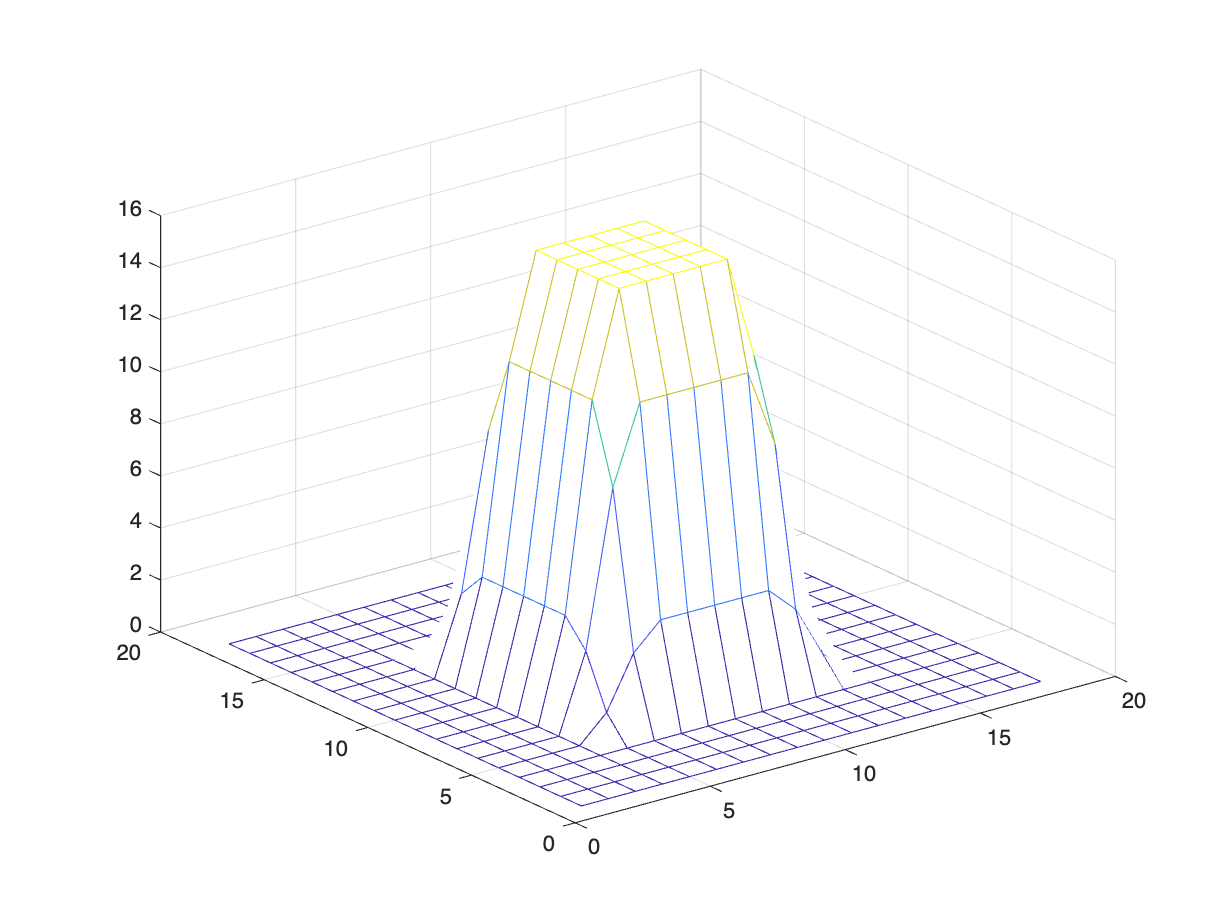

mesh(Aout)

figure
mesh(Aout_sep)

Bout = conv2(hB,A1);
Bout_sep = conv2(transpose(h2),h1,A1);
size(Bout)

ans =     18    18


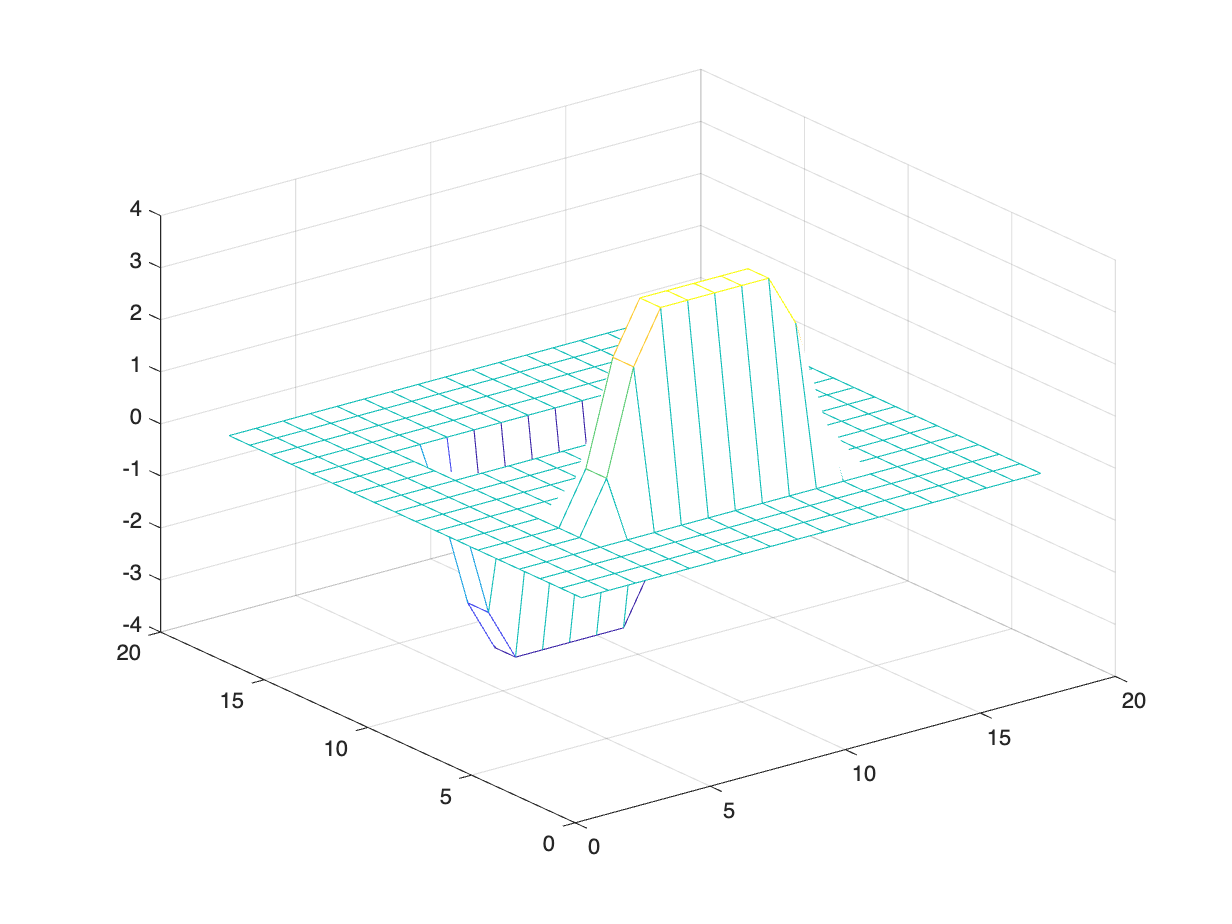

mesh(Bout)

figure
mesh(Bout_sep)

Btout = conv2(transpose(hB),A1);
Btout_sep = conv2(transpose(h1),h2,A1);
size(Btout)

ans =     18    18


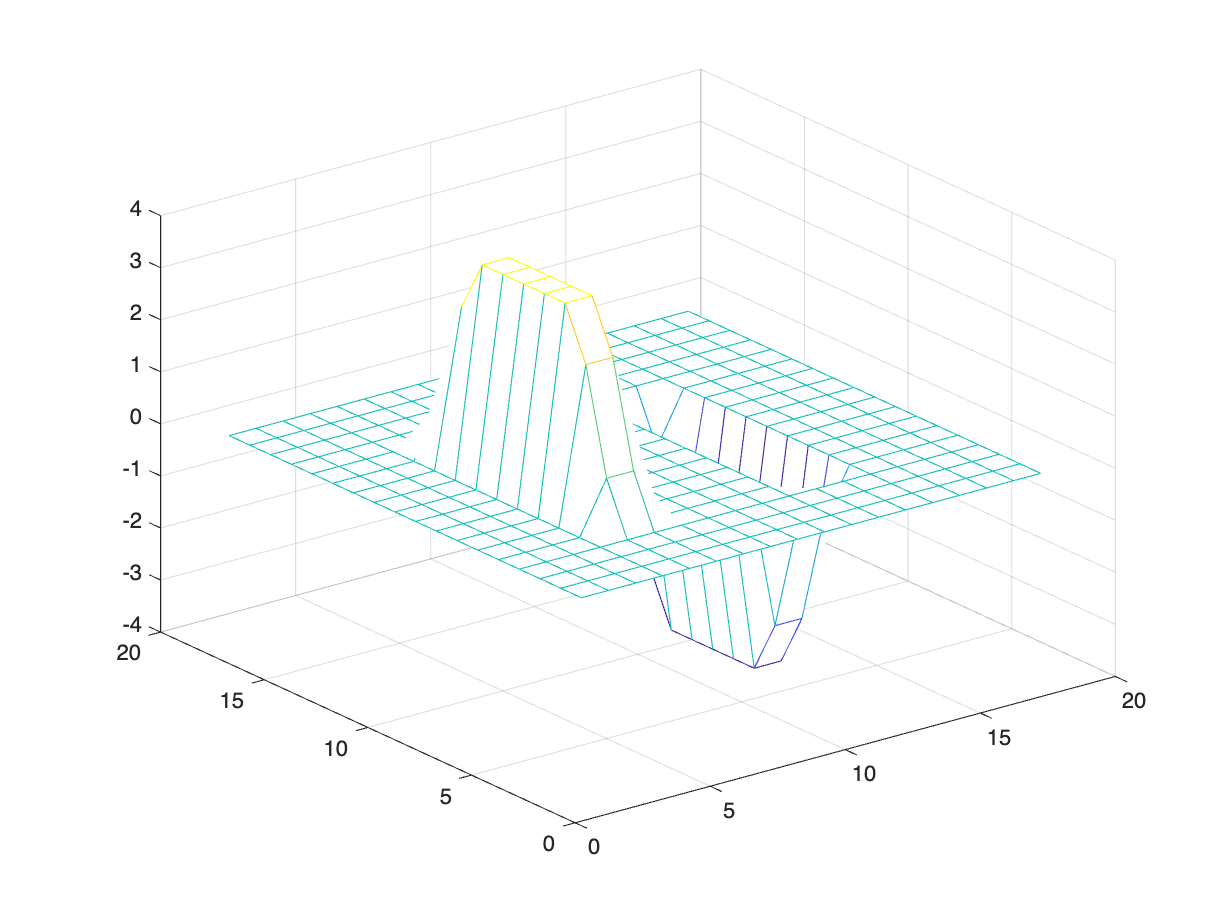

mesh(Btout)

figure
mesh(Btout_sep)

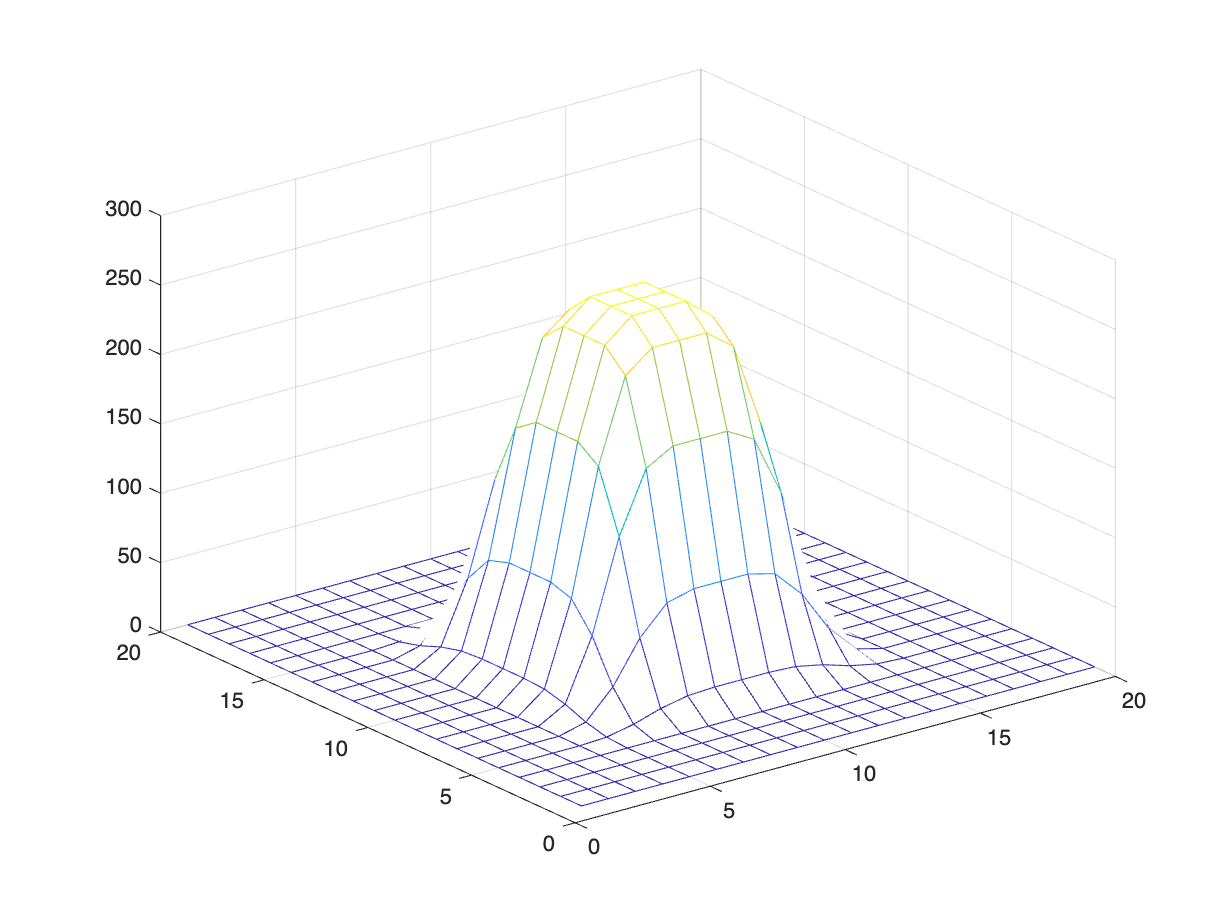

m4 = conv2(transpose(h3), h3, A1);
mesh(m4)

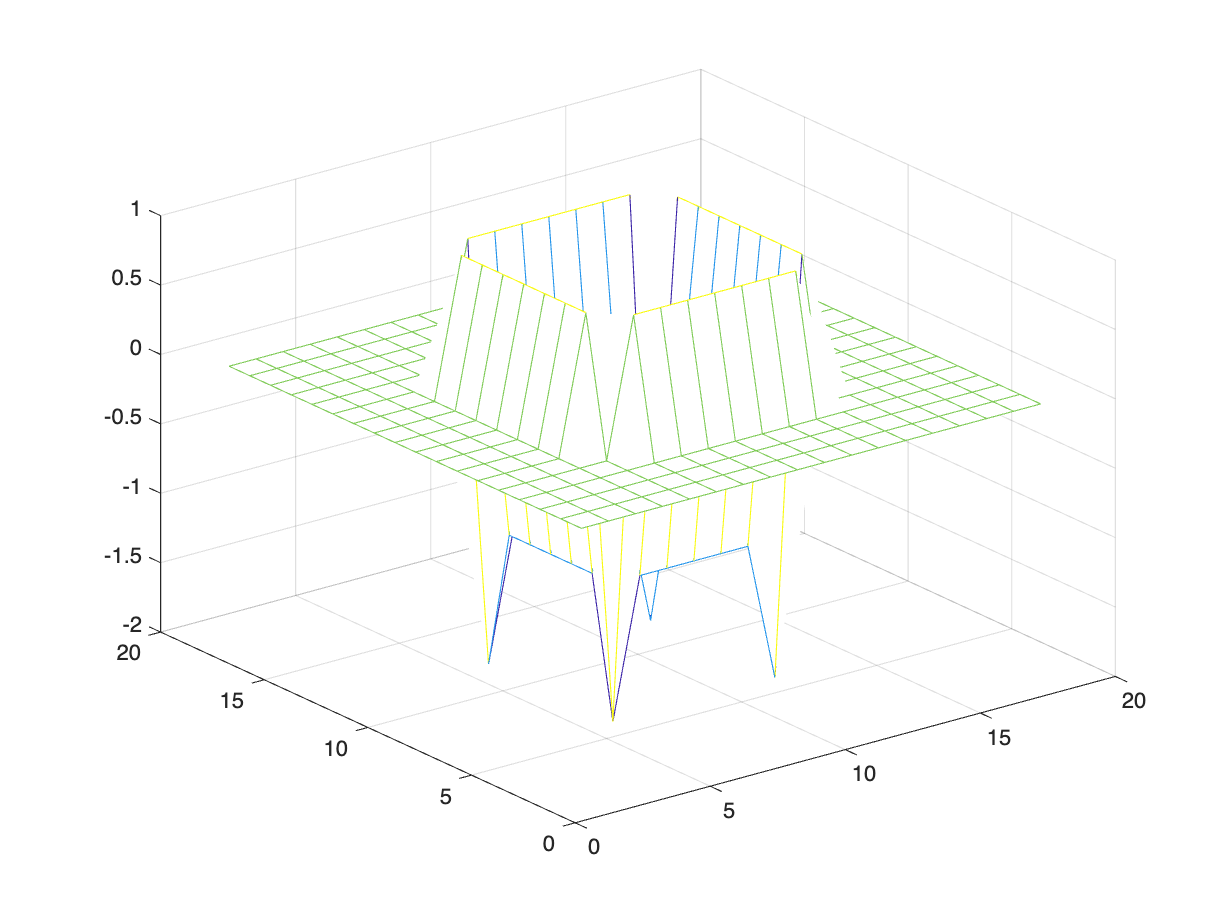

size(m4);
hL = fspecial('laplacian', 0.0);
YL = conv2(hL, A1);
mesh(YL)

## Part 2

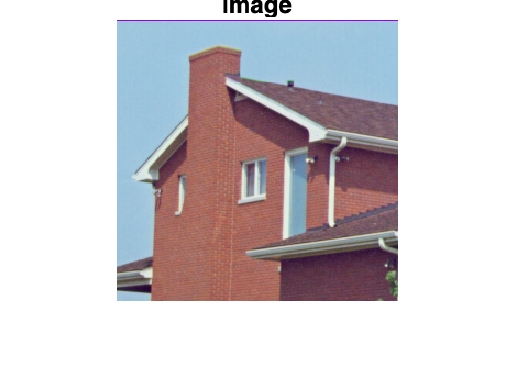

i1 = imread('4.1.05.tiff');
figure;
imshow(i1)
title('Image');

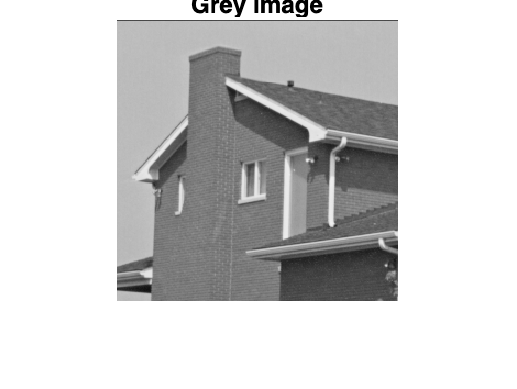

i1grey = rgb2gray(i1);
figure;
imshow(i1grey)
title('Grey Image');

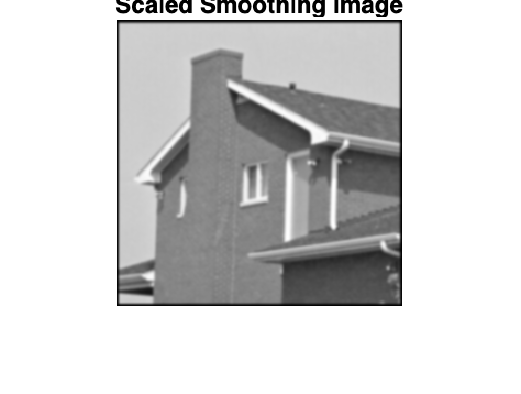

s3 = h3/16;
scaled = conv2(transpose(s3), s3, i1grey);
figure;
imshow(scaled, [])
title('Scaled Smoothing Image');

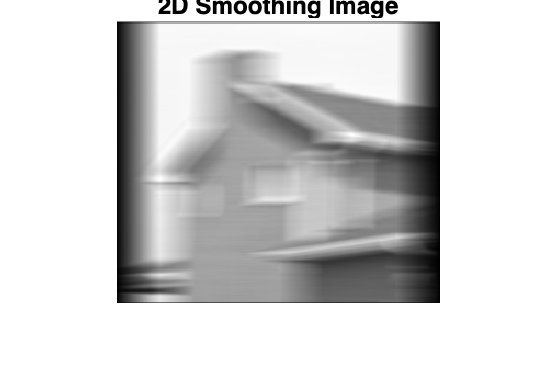

hS = ones(2,40)/80;
two_dim = conv2(hS,i1grey);
figure;
imshow(two_dim, [])
title('2D Smoothing Image');

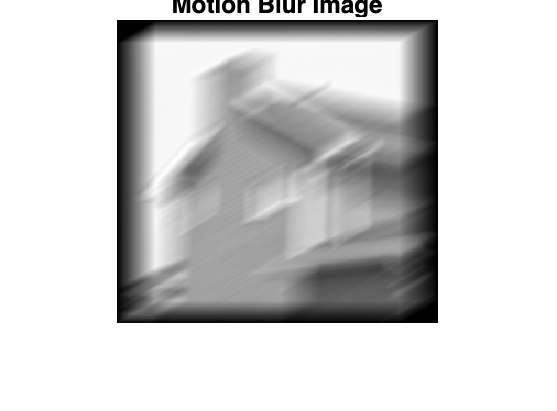

hM = fspecial('motion', 41, 30);
motion = conv2(hM,i1grey);
figure;
imshow(motion, [])
title('Motion Blur Image');

## Part 3

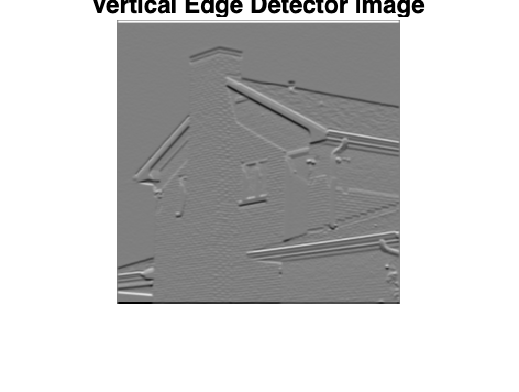

vertical_edge_detector = conv2(hB,i1grey);
figure;
imshow(vertical_edge_detector, [])
title('Vertical Edge Detector Image');

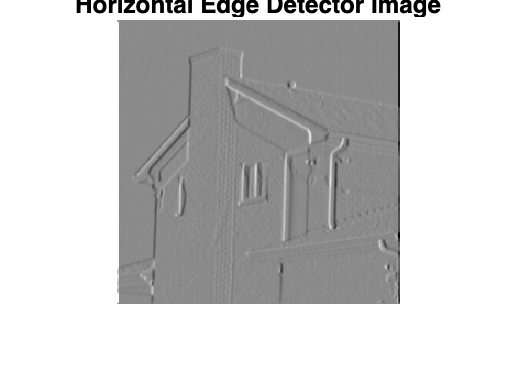

horizontal_edge_detector = conv2(hB',i1grey);
figure;
imshow(horizontal_edge_detector, [])
title('Horizontal Edge Detector Image');

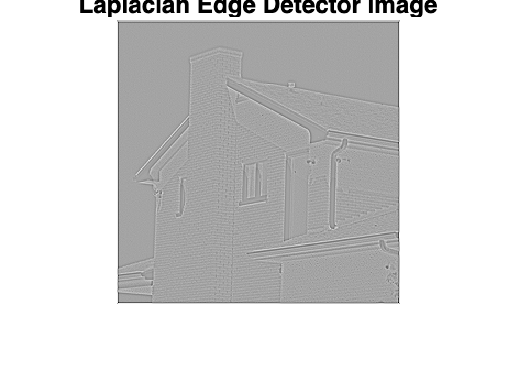

laplacian_edge_detector = conv2(hL,i1grey);
figure;
imshow(laplacian_edge_detector, [])
title('Laplacian Edge Detector Image');

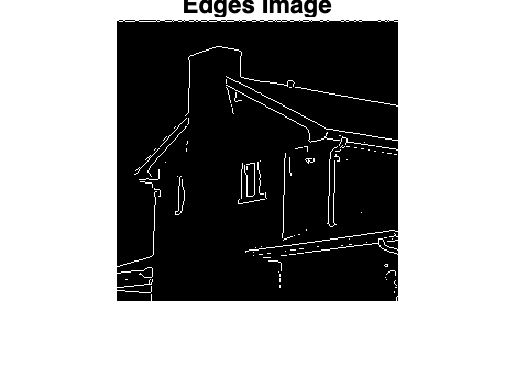

edge1 = edge(i1grey);
figure;
imshow(edge1, [])
title('Edges Image');

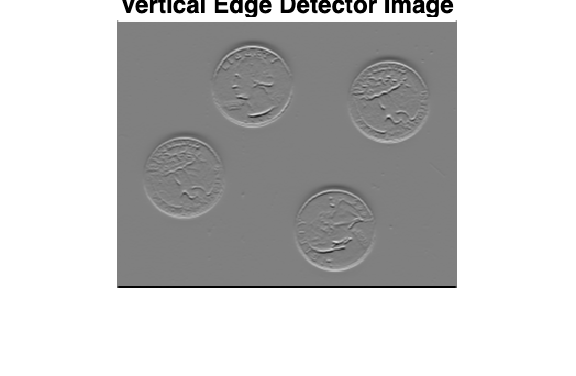

i2 = imread('eight.tif');
vertical_edge_detector = conv2(hB,i2);
figure;
imshow(vertical_edge_detector, [])
title('Vertical Edge Detector Image');

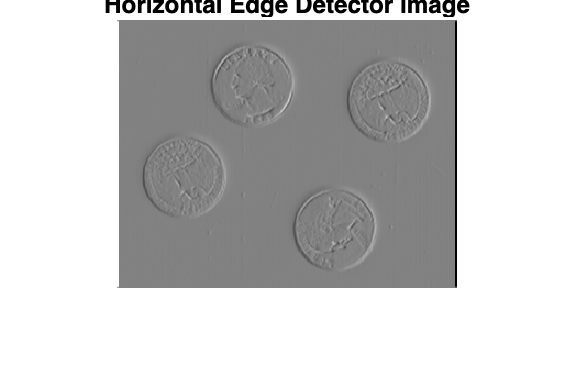

horizontal_edge_detector = conv2(hB',i2);
figure;
imshow(horizontal_edge_detector, [])
title('Horizontal Edge Detector Image');

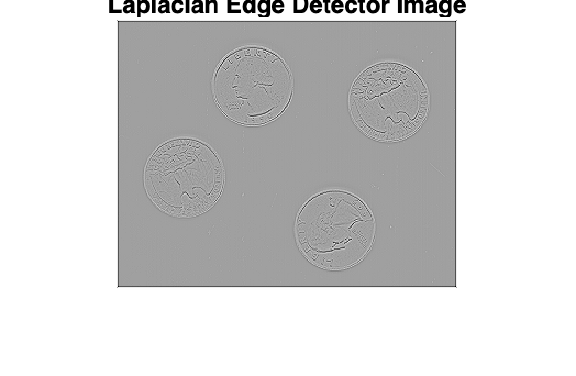

laplacian_edge_detector = conv2(hL,i2);
figure;
imshow(laplacian_edge_detector, [])
title('Laplacian Edge Detector Image');

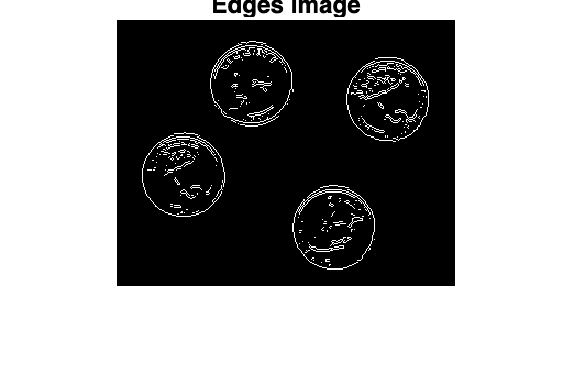

edge1 = edge(i2);
figure;
imshow(edge1, [])
title('Edges Image');

## Part 4

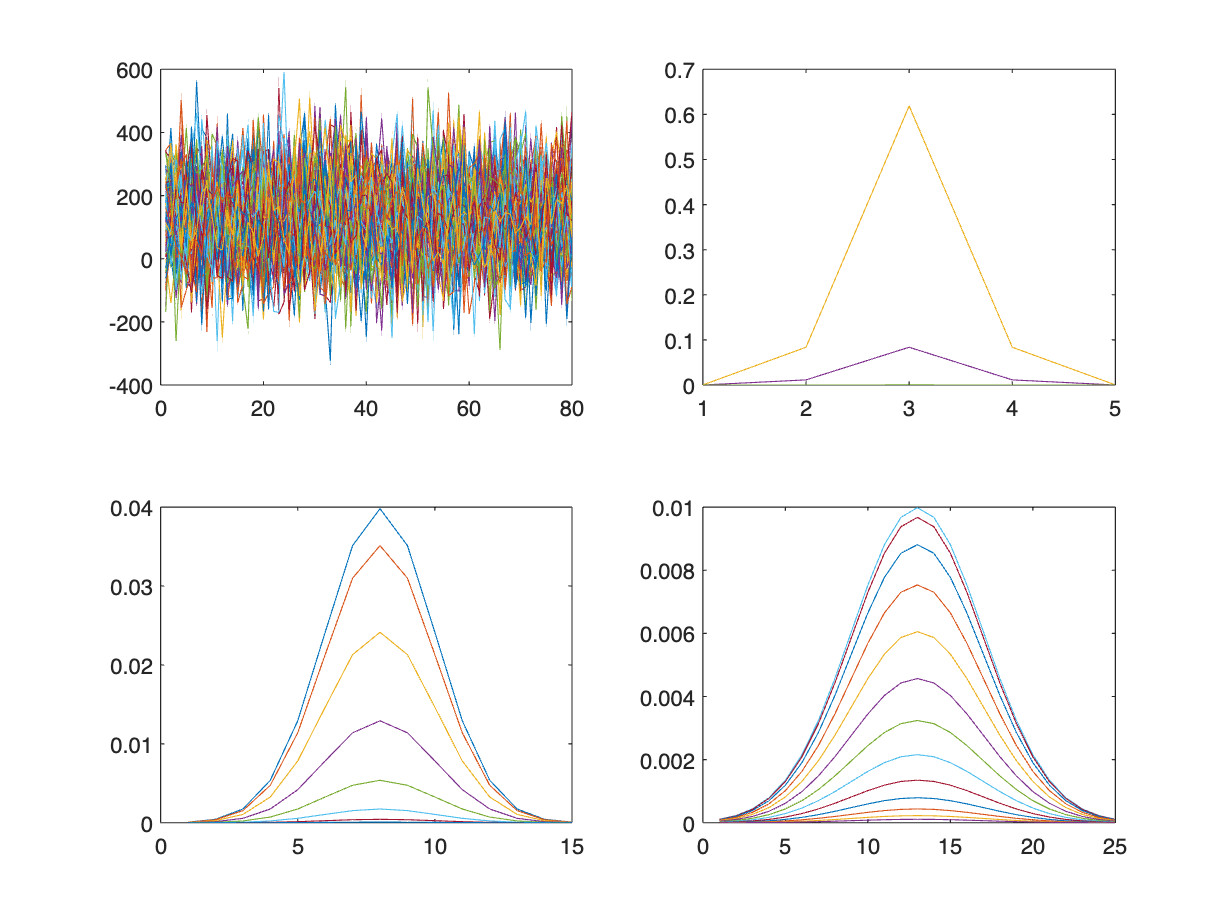

inoise = 128 + 128*randn(80);
hG1 = fspecial('gaussian', 5, 0.5);
hG2 = fspecial('gaussian', 15, 2.0);
hG3 = fspecial('gaussian', 25, 4.0);

figure;
subplot(2,2,1)
plot(inoise)
subplot(2,2,2)
plot(hG1)
subplot(2,2,3)
plot(hG2)
subplot(2,2,4)
plot(hG3)

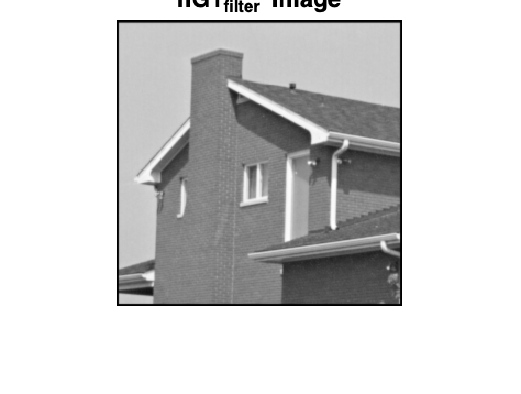

V = 0;
i1noise = double(i1grey);
hG1_filter = conv2(hG1,i1noise);
figure;
imshow(hG1_filter, [])
title('hG1_filter Image');

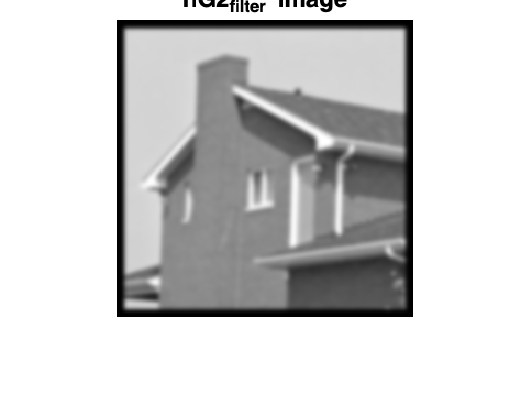

hG2_filter = conv2(hG2,i1noise);
figure;
imshow(hG2_filter, [])
title('hG2_filter Image');

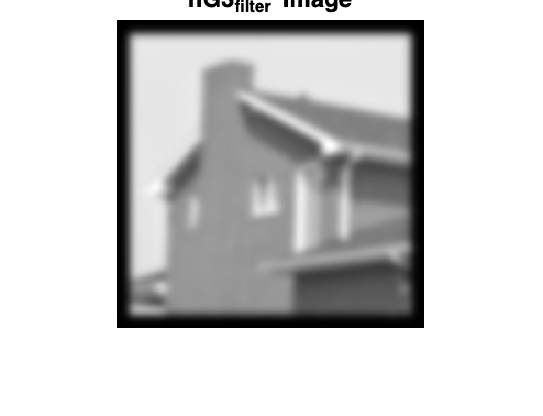

hG3_filter = conv2(hG3,i1noise);
figure;
imshow(hG3_filter, [])
title('hG3_filter Image');

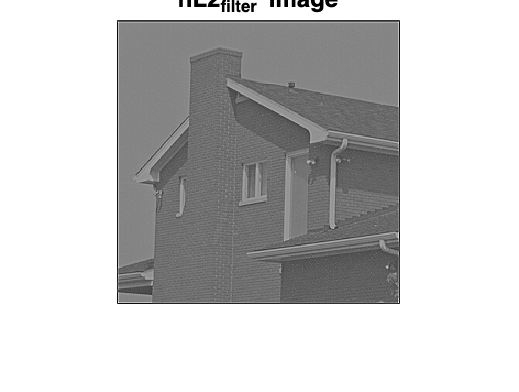

hL2 = [0, -1, 0; -1, 5, -1; 0, -1, 0];
hL2_filter = conv2(hL2,i1noise);
figure;
imshow(hL2_filter, [])
title('hL2_filter Image');

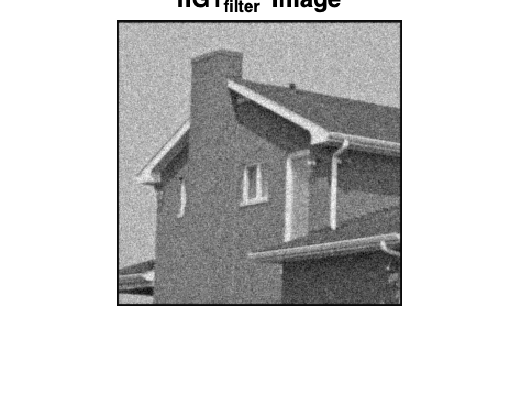

V = 20;
i1noise = double(i1grey) + V*randn(size(i1grey));
hG1_filter = conv2(hG1,i1noise);
figure;
imshow(hG1_filter, [])
title('hG1_filter Image');

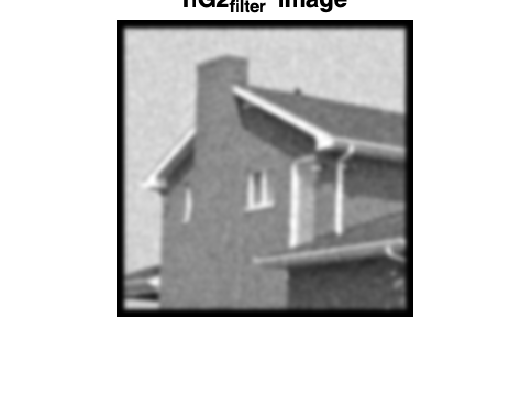

hG2_filter = conv2(hG2,i1noise);
figure;
imshow(hG2_filter, [])
title('hG2_filter Image');

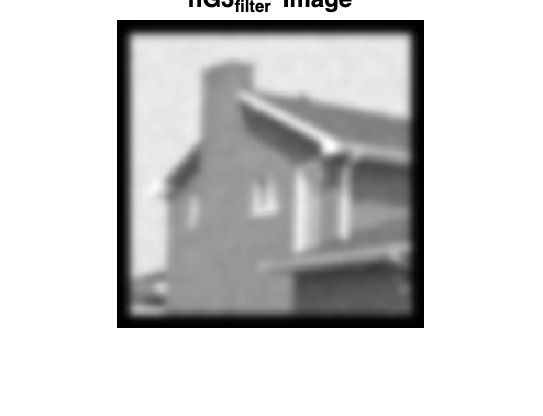

hG3_filter = conv2(hG3,i1noise);
figure;
imshow(hG3_filter, [])
title('hG3_filter Image');

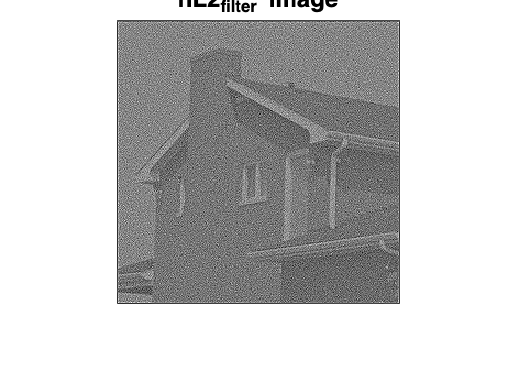

hL2 = [0, -1, 0; -1, 5, -1; 0, -1, 0];
hL2_filter = conv2(hL2,i1noise);
figure;
imshow(hL2_filter, [])
title('hL2_filter Image');

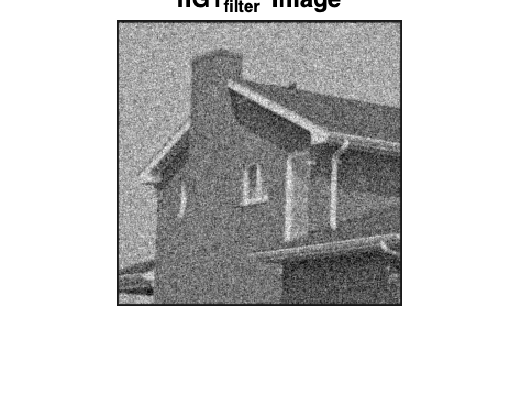

V = 40;
i1noise = double(i1grey) + V*randn(size(i1grey));
hG1_filter = conv2(hG1,i1noise);
figure;
imshow(hG1_filter, [])
title('hG1_filter Image');

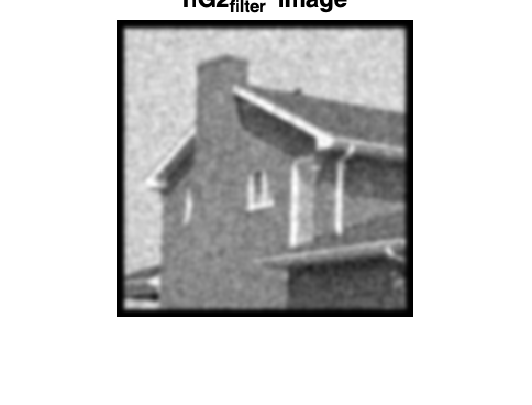

hG2_filter = conv2(hG2,i1noise);
figure;
imshow(hG2_filter, [])
title('hG2_filter Image');

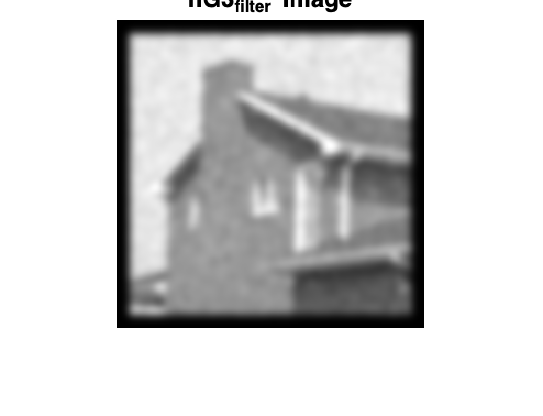

hG3_filter = conv2(hG3,i1noise);
figure;
imshow(hG3_filter, [])
title('hG3_filter Image');

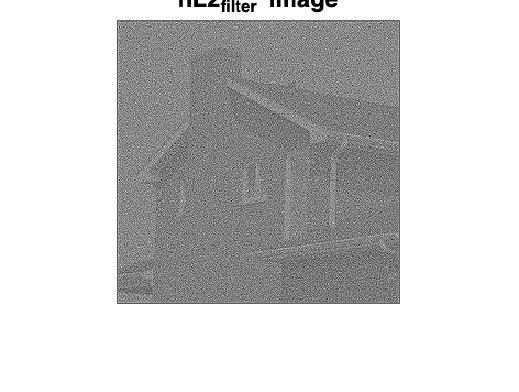

hL2 = [0, -1, 0; -1, 5, -1; 0, -1, 0];
hL2_filter = conv2(hL2,i1noise);
figure;
imshow(hL2_filter, [])
title('hL2_filter Image');